% basic parameter

% data length, fs, f
L = 153600; fs = 614.4e6; 
% f = (1/4000)^(2n)
f = 34.35974e6;
f = 34359740;
dt = 1/fs;
t = (1:L)'*dt;
singal_tone = 0;
rewrite = 1;

q = 0.5; i = 0.5;

%% singal tone
if singal_tone == 1
% generate data
x = q*sin(2*pi*f*t)+i*cos(2*pi*f*t)*1j;

% figure;
% plot(t,abs(x));

% plot the singal PSD
figure;
pwelch(x,2^9,[],[],614.4e6,'centered');
% figure;
% plot(real(x),imag(x),'.');

% % senduit to SoC
% send_RFSoC([],x,x);

% % receive from SoC
% [yBB,rxdata] = recv_RFSoC([]);

% % plot the PSD
% figure;
% pwelch(yBB,2^9,[],[],614.4e6,'centered');
% figure;
% plot(t,abs(yBB));
% hold on
% plot(t,abs(x));
% figure;
% plot(real(yBB),imag(yBB),'.');
% hold on
% plot(real(x),imag(x),'.');

% % both files should be uploaded manually
% % receive from python and compare
% rx_py = load('rx.mat');
% yBB_py = rx_py.yBB;
% figure;
% pwelch([yBB yBB_py],2^12,[],[],614.4e6,'centered');
% legend;

% % check tx.amt
% tx_py = load('tx.mat');
% xBB_py = tx_py.ch2;
% figure;
% pwelch(xBB_py,2^12,[],[],614.4e6,'centered');
% legend;

% % rewrite the tx file
% if rewrite
%     x1 = sin(2*pi*2*f*t)-cos(2*pi*2*f*t)*1j;
%     pwelch(x1,2^9,[],[],614.4e6,'centered');
%     tx_py.ch2 = x1;
% end
% save('tx_new.mat','tx_py');

else

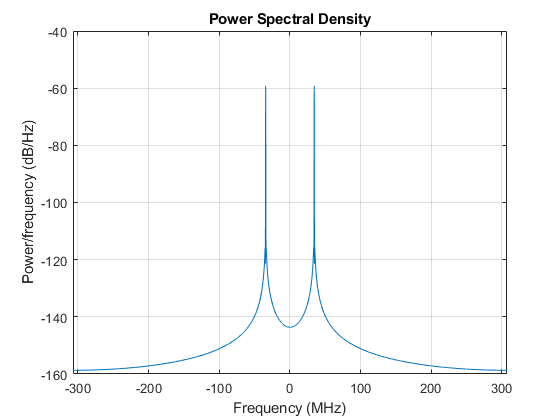

%% double tone
% x = (q*sin(2*pi*2*f*t)*1j + q*cos(2*pi*2*f*t)) + ((q*sin(2*pi*1*f*t)*1j + q*cos(2*pi*1*f*t)));
x = q*sin(2*pi*f*t)+i*cos(2*pi*f*t)*1j + q*cos(2*pi*f*t)+i*sin(2*pi*f*t)*1j;

% plot the singal PSD
figure;
pwelch(x,2^12,[],[],614.4e6,'centered');

% send it to SoC
send_RFSoC([],x,x);

% receive from SoC
[yBB,rxdata] = recv_RFSoC([]);

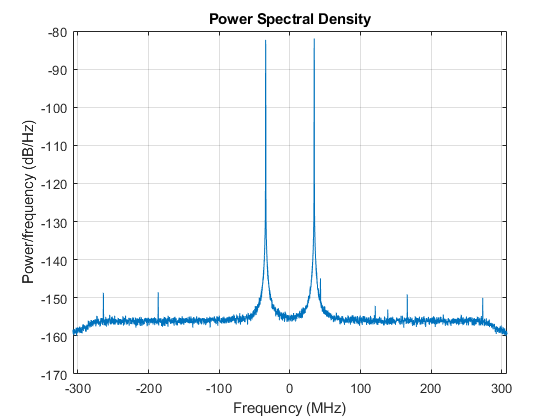

% plot the PSD
figure;
pwelch(yBB,2^12,[],[],614.4e6,'centered');

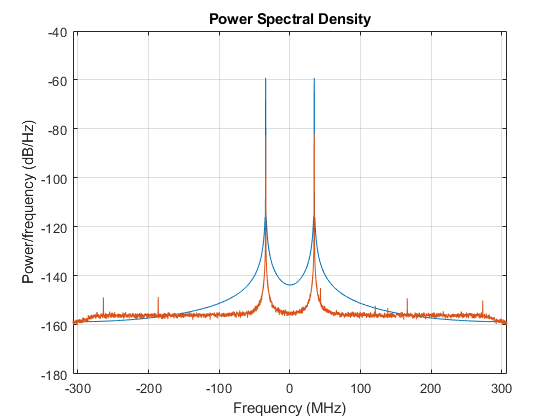

figure;
pwelch([x yBB],2^12,[],[],614.4e6,'centered');

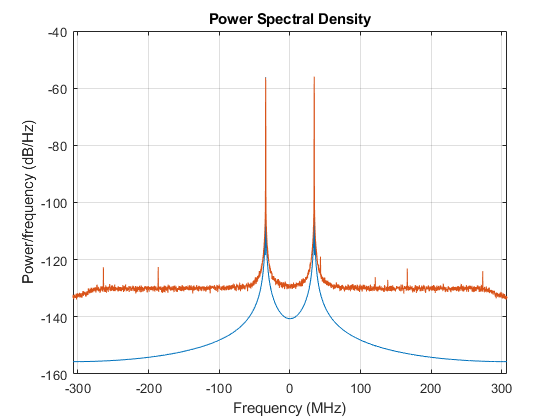

%rms归一化
yBB = yBB/(rms(yBB));
x = x/(rms(x));
figure;
pwelch([x yBB],2^12,[],[],614.4e6,'centered');

% figure;
% plot(real(yBB),imag(yBB),'.');
% hold on
% plot(real(x),imag(x),'.');

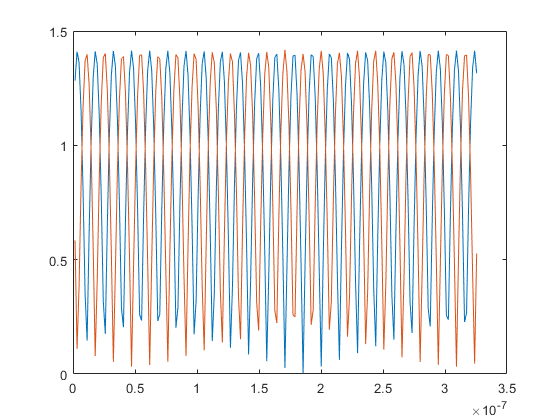

% Interpolation 

tp = (1:10*L)'*(0.1*dt);
xp = interp1(t,x,tp,'spline');
yBBp=interp1(t,yBB,tp,'spline');

t1 = 1;
t2 = 200;
figure;
plot(t(t1:t2),abs(x(t1:t2)));
hold on
plot(t(t1:t2),abs(yBB(t1:t2)));

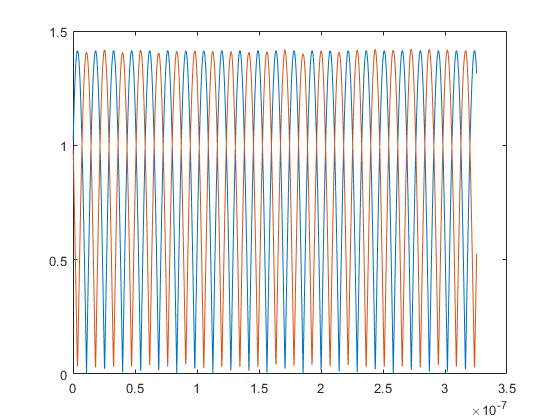


t1 = 1;
t2 = 2000;
figure;
plot(tp(t1:t2),abs(xp(t1:t2)));
hold on
plot(tp(t1:t2),abs(yBBp(t1:t2)));


% delay = 240;
% 
% figure;
% plot((tp(t1+delay:t2+delay)-tp(t1+delay)),abs(xp(t1+delay:t2+delay)));
% hold on
% plot(tp(t1:t2),abs(yBBp(t1:t2)));

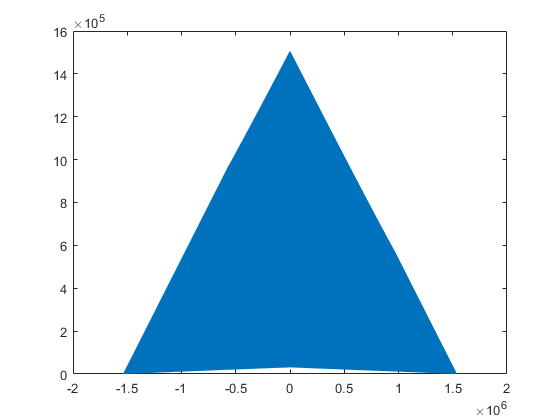

% align
t1 = 1300;
t2 = 1900;
[r,lags] = xcorr(yBBp, xp);
figure;
plot(lags,abs(r));

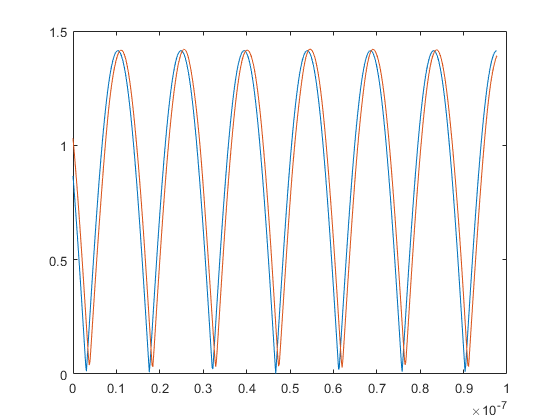

[val,idx]=max(abs(r));
offset=lags(idx);


figure;
plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
t3 = t1+offset;
t4 = t2+offset;
hold on
plot((tp(t3:t4)-tp(t3)),abs(yBBp(t3:t4)));

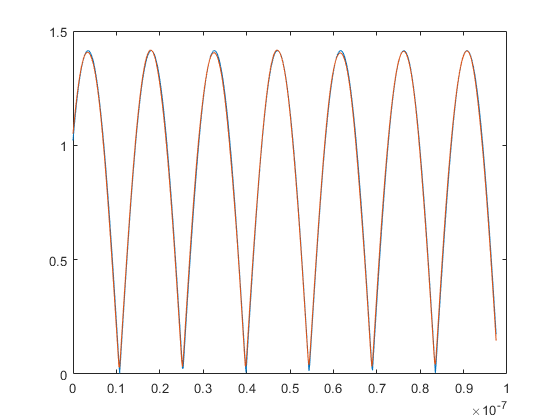


error = 1e12;
index = 0;
temp = 0;
for k=(-20:20)
    temp = sum((abs(yBBp(t3+k:t4+k))-abs(xp(t1:t2))).^2);
%     disp(temp)
    if(temp < error)
        error = temp;
        index = k;
    end
end
% disp(error)
% disp(index)
% figure;
% plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
% hold on
% k = 7;
% plot((tp((t3+k):(t4+k))-tp(t3+k)),abs(yBBp((t3+k):(t4+k))));
% temp = sum((abs(yBBp(t3+k:t4+k))-abs(xp(t1:t2))).^2);
% disp(temp)
offset1 = offset+index+1;

% t1 = 12300;
% t2 = 12900;
% figure;
% plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
% t3 = t1+offset1;
% t4 = t2+offset1;
% hold on
% plot((tp(t3:t4)-tp(t3)),abs(yBBp(t3:t4)));

figure;
t1 = 1;
t2 = 600;
plot((tp(t1:t2)-tp(t1)),abs(xp(t1:t2)));
t3 = t1;
t4 = t2;
yBBp1 = circshift(yBBp, -offset1);
hold on
plot((tp(t3:t4)-tp(t3)),abs(yBBp1(t3:t4)));


% figure;
% t1 = 1230;
% t2 = 1290;
% plot((t(t1:t2)-t(t1)),abs(x(t1:t2)));
% t3 = t1+round(offset1/10);
% t4 = t2+round(offset1/10);
% hold on
% plot((t(t3:t4)-t(t3)),abs(yBB(t3:t4)));

% figure;
% t1 = 1230;
% t2 = 1290;
% plot((t(t1:t2)-t(t1)),abs(x(t1:t2)));
% t3 = t1;
% t4 = t2;
% yBB1 = circshift(yBB, round(-offset1/10));
% 
% hold on
% plot((t(t3:t4)-t(t3)),abs(yBB1(t3:t4)));
% yBB1 is the shifted signal
% yBBp1 is the shifted signal

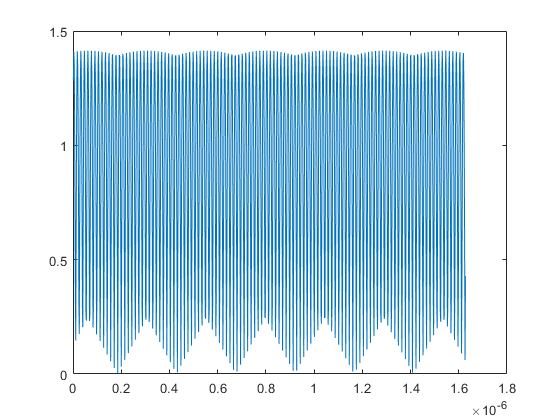

%% phase
save("asdasd.mat", "yBB", "x", "t", "tp", "xp", "yBBp")

% FFT
% input signal
Y = fft(x,L);

Y1 = Y.*exp((15*pi/180)*1j);
figure;
plot(t(1:1000), abs(x(1:1000)))

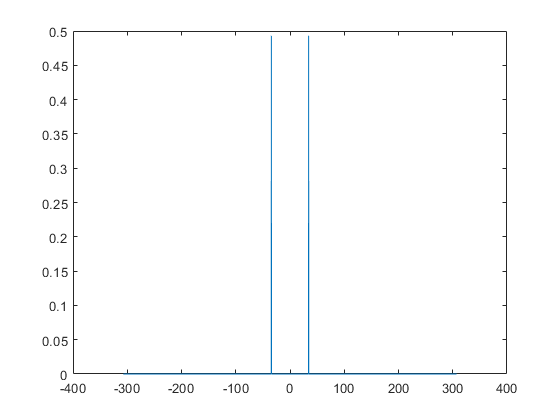


fw = fs*(-(L/2):(L/2)-1)/L;
P = abs(Y/L).^2;
W = angle(Y)*180/pi;
W1 = angle(Y1)*180/pi;
figure;
plot(fw/1e6,circshift(P,L/2))

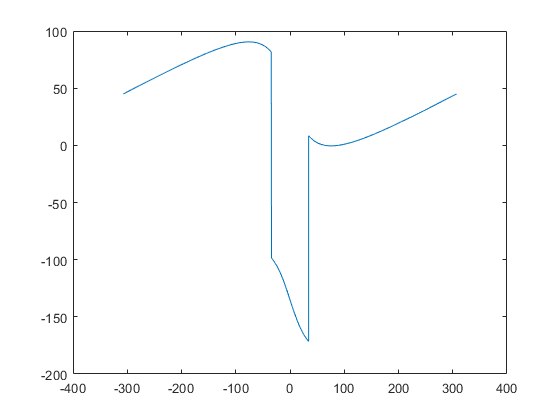

% figure;
% plot(real(Y),imag(Y),'.');
% figure;
% plot(real(x),imag(x),'.');
figure;
W = circshift(W,L/2);
plot(fw/1e6,W)

% hold on
% W1 = circshift(W1,L/2);
% 
% plot(fw/1e6,W1)
% x_ph = ifft(Y);
% figure;
% plot(t(1:1000), abs(x(1:1000)))
% hold on
% plot(t(1:1000), abs(x_ph(1:1000)))

% received signal
% Y2 = fft(yBB1,L);
% fw = fs*(-(L/2):(L/2)-1)/L;
% Y3 = Y2.*exp((-20*pi/180)*1j);
% P2 = abs(Y2/L).^2;
% W2 = angle(Y2)*180/pi;
% W3 = angle(Y3)*180/pi;
% figure;
% plot(fw/1e6,circshift(P2,L/2))
% figure;
% plot(real(Y),imag(Y),'.');
% figure;
% plot(real(x),imag(x),'.');
% figure;
% W2 = circshift(W2,L/2);
% W3 = circshift(W3,L/2);
% plot(fw(1:1000)/1e6,W2(1:1000))
% figure;
% plot(fw(1:1000)/1e6,W3(1:1000))

% yBB2 = ifft(Y3);


% AM-AM
% AM-PM

% figure;
% plot(abs(xp),abs(yBBp1),'.')
% figure;
% PM = mod((angle(yBBp1)-angle(xp)+pi),2*pi)-pi;
% PM1 = (angle(yBBp1)-angle(xp))+2*pi;
% plot(abs(xp), (mod(PM1,pi)-0)*(180/pi),'.')



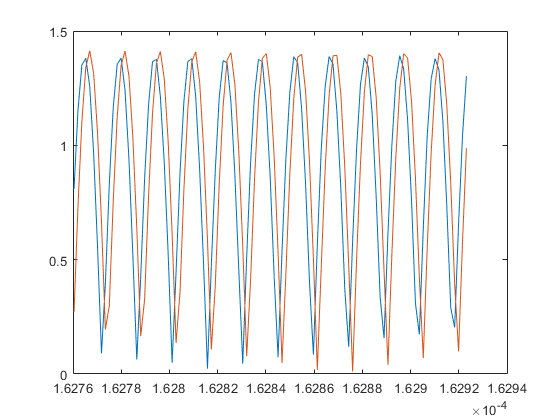

% originalFs = fs*10;
% desiredFs = fs;

% [p,q] = rat(desiredFs / originalFs)
% disp(p)

yasd = downsample(yBBp1, 10, 9);
figure;
plot(t(100000:100100),abs(yasd(100000:100100)))
hold on
plot(t(100000:100100),abs(x(100000:100100)))

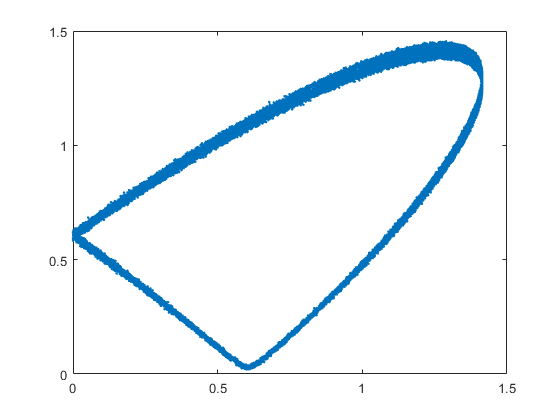

% AM-AM
% AM-PM
figure;
plot(abs(x(100000:120000)), abs(yasd(100000:120000)),'.')

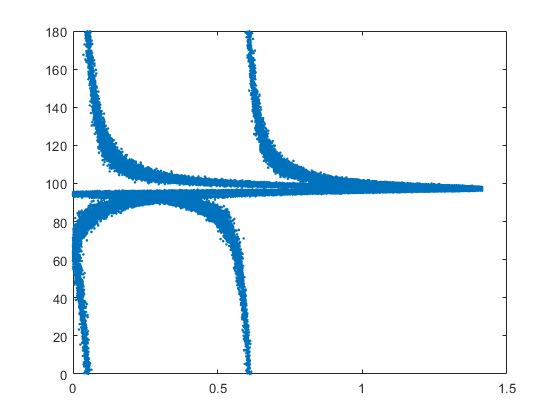


figure;
PM = mod((angle(yasd)-angle(x)+pi),2*pi)-pi;
PM1 = (angle(yasd)-angle(x))+2*pi;
plot(abs(x), (mod(PM1,pi)-0)*(180/pi),'.')

% % IFFT
% x1 = ifft(Y);

% %% test offset
% t = (0:0.05:100);
% t1 = 1; t2 = 50;
% delay = 23;
% t3 = t1 + delay;
% t4 = t2 + delay;
% 
% x1 = sin(2*pi*t(t1:t2));
% x2 = sin(2*pi*t(t3:t4));
% 
% figure;
% plot(t(t1:t2),x1);
% hold on 
% plot((t(t3:t4)-t(t3)), x2);
% 
% %% find the offset
% [r,lags] = xcorr(x1,x2);
% figure;
% plot(lags,r);
% [val,idx]=max(r);
% offset=lags(idx);
% 
% %% verify
% delay = delay - offset;
% t3 = t1 + delay;
% t4 = t2 + delay;
% 
% x2 = sin(2*pi*t(t3:t4));
% 
% figure;
% plot(t(t1:t2),x1);
% hold on 
% plot((t(t3:t4)-t(t3)), x2);

end